# **PM4Sand model undrained cyclic simple shear element**

The original model is from 2D Undrained Cyclic Direct Simple Shear Test Using One Element at University of Washington, Department of Civil and Environmental Eng by Geotechnical Eng Group L. Chen, P. Arduino - Feb 2018.

% =========================================================================
% PM4Sand Undrained Cyclic Simple Shear Element Test (MATLAB)
% Converted from Python/OpenSeesPy code by Zhongze Xu, UT Austin
% Uses OpenSees MATLAB interface with ops. prefix
%
% Basic Units: m, kN, s
% =========================================================================
% Original reference:
%   2D Undrained Cyclic Direct Simple Shear Test Using One Element
%   University of Washington, Dept. of Civil and Environmental Eng
%   Geotechnical Eng Group, L. Chen, P. Arduino - Feb 2018
% =========================================================================
 
%% Input Variables
% nDMaterial('PM4Sand', matTag, Dr, G0, hpo, rho, P_atm, h0, e_max, e_min,
%            nb, nd, Ado, z_max, c_z, c_e, phi_cv, nu, g_degr, c_dr, c_kaf,
%            Q, R, m_par, F_sed, p_sed)

clc;
clear;

opsmat = OpenSeesMatlab();
ops = opsmat.opensees;

atm      = -101.325;
sig_v0   = 2.0 * atm;   % initial vertical stress (kPa)
CSR      = 0.2;          % cyclic stress ratio
Cycle_max = 5;           % maximum number of cycles
strain_in = 5.0e-6;      % strain increment
K0       = 0.5;
nu       = K0 / (1 + K0); % Poisson's ratio
devDisp  = 0.03;          % cutoff shear strain (m)
perm     = 1e-9;          % permeability
 
%% Primary Parameters
Dr  = 0.5;
G0  = 476.0;
hpo = 0.53;   % contraction rate parameter
rho = 1.42;   % mass density (kN·s²/m⁴)
 
%% Secondary Parameters
P_atm  = 101.325;
h0     = -1.0;   % adjusts plastic modulus ratio (negative = auto)
e_max  = 0.8;
e_min  = 0.5;
e_ini  = e_max - (e_max - e_min) * Dr;  % initial void ratio
nb     = 0.5;    % bounding surface parameter, nb >= 0
nd     = 0.1;    % dilatancy surface parameter, nd >= 0
Ado    = -1.0;   % dilatancy parameter (negative = auto)
z_max  = -1.0;   % fabric-dilatancy tensor parameter (negative = auto)
c_z    = 250.0;  % fabric-dilatancy tensor parameter
c_e    = -1.0;   % fabric-dilatancy tensor parameter (negative = auto)
phi_cv = 26.0;   % critical state effective friction angle
g_degr = 2.0;    % elastic modulus degradation variable
c_dr   = -1.0;   % rotated dilatancy surface variable (negative = auto)
c_kaf  = -1.0;   % sustained static shear effect variable (negative = auto)
Q      = 10.0;   % critical state line parameter
R      = 1.5;    % critical state line parameter
m_par  = 0.01;   % yield surface constant
F_sed  = -1.0;   % reconsolidation elastic moduli reduction (negative = auto)
p_sed  = -1.0;   % mean effective stress for reconsolidation strains (negative = auto)
 
%% Rayleigh Damping Parameters
% ops.rayleigh(alphaM, betaK, betaKinit, betaKcomm)
damp   = 0.02;
omega1 = 0.2;
omega2 = 20.0;
a1 = 2.0 * damp / (omega1 + omega2);  % alphaM
a0 = a1 * omega1 * omega2;             % betaK

%% Build Model
ops.wipe();
ops.model("basic", '-ndm', 2, '-ndf', 3);
 
% Node coordinates
x1 = 0.0;  y1 = 0.0;
x2 = 1.0;  y2 = 0.0;
x3 = 1.0;  y3 = 1.0;
x4 = 0.0;  y4 = 1.0;
 
% Create nodes
ops.node(1, x1, y1);
ops.node(2, x2, y2);
ops.node(3, x3, y3);
ops.node(4, x4, y4);
 
% Boundary conditions
% fix(nodeTag, dof1, dof2, dof3)
ops.fix(1, 1, 1, 1);
ops.fix(2, 1, 1, 1);
ops.fix(3, 0, 0, 1);
ops.fix(4, 0, 0, 1);
 
% Tie nodes 3 and 4 to have equal displacement in DOFs 1 & 2
ops.equalDOF(3, 4, 1, 2);
 
%% Define Material
% nDMaterial PM4Sand
ops.nDMaterial('PM4Sand', 1, Dr, G0, hpo, rho, P_atm, h0, e_max, e_min, ...
    nb, nd, Ado, z_max, c_z, c_e, phi_cv, nu, g_degr, c_dr, c_kaf, ...
    Q, R, m_par, F_sed, p_sed);

[OpenSees] PM4Sand nDmaterial - Written: L.Chen, P.Arduino, U.Washington


 
%% Define Element
% SSPquadUP: fully-saturated u-p formulation
ops.element('SSPquadUP', 1, 1, 2, 3, 4, 1, 1.0, 2.2e6, 1.0, perm, perm, e_ini, 1.0e-5);

[OpenSees] SSPquadUP element - Written: C.McGann, P.Arduino, P.Mackenzie-Helnwein, U.Washington




%% Recorders
ops.recorder('Node', '-file', 'output_data/Cycdisp.txt',  '-time', '-node', 1, 2, 3, 4, '-dof', 1, 2, 'disp');
ops.recorder('Node', '-file', 'output_data/CycPP.txt',    '-time', '-node', 1, 2, 3, 4, '-dof', 3, 'vel');
ops.recorder('Element', '-file', 'output_data/Cycstress.txt', '-time', '-ele', 1, 'stress');
ops.recorder('Element', '-file', 'output_data/Cycstrain.txt', '-time', '-ele', 1, 'strain');

[OpenSeesMatlab] Model summary
  Nodes: 4
  Plane elements: 1
  MP constraints: 1


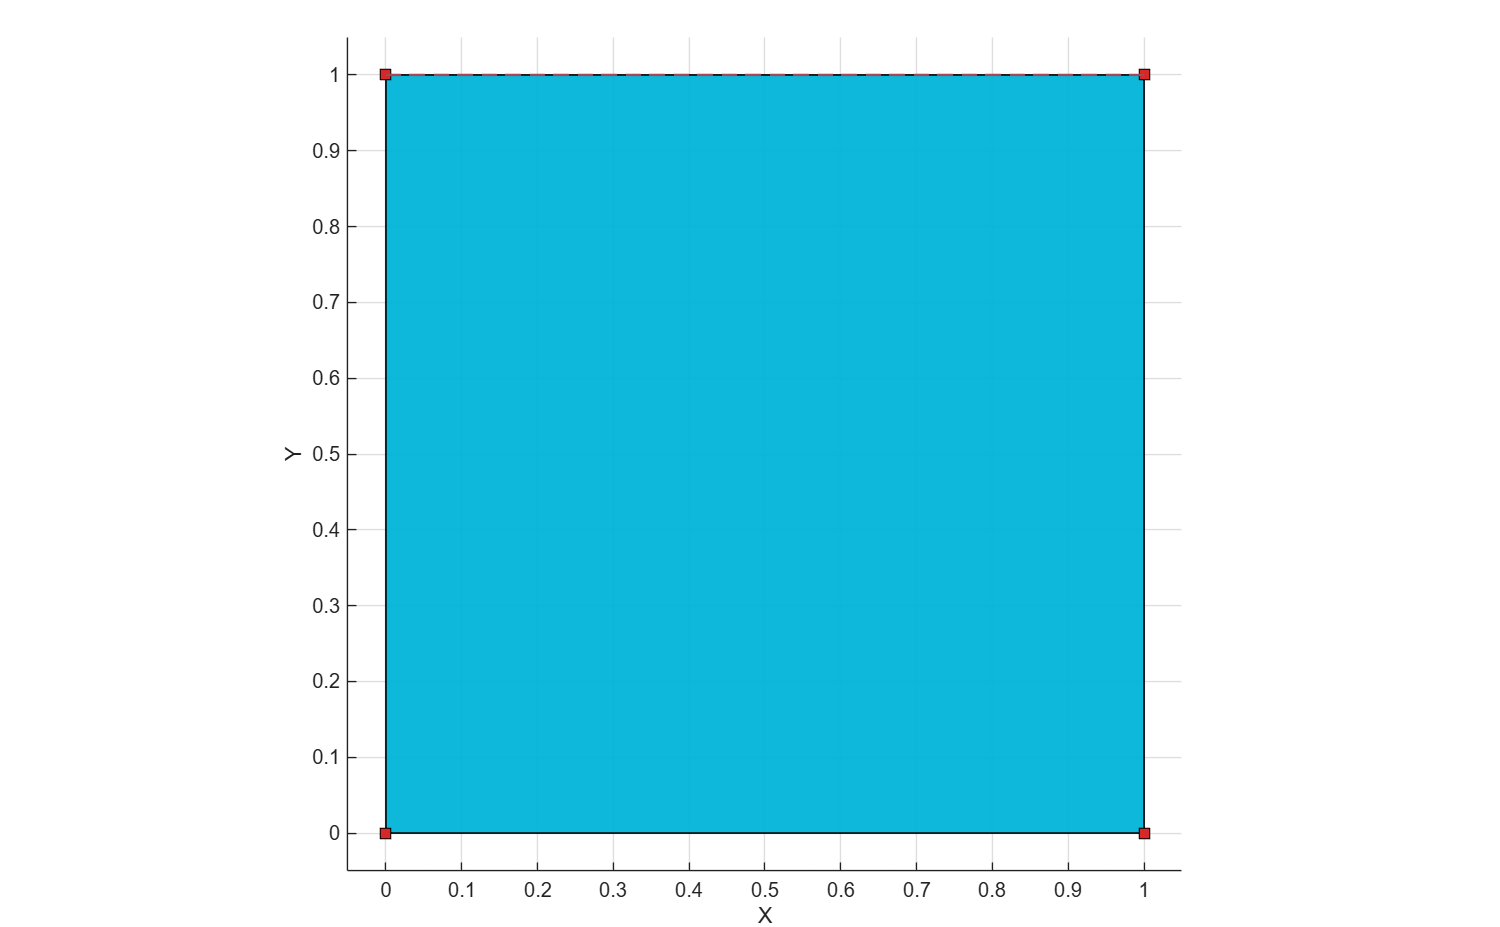

opts = opsmat.vis.defaultPlotModelOptions();
opts.loads.showNodal = true;
opts.loads.scale = 0.001;
opsmat.vis.plotModel(opts=opts);

%% Analysis Settings
ops.constraints('Transformation');
ops.test('NormDispIncr', 1.0e-5, 35, 0);
ops.algorithm('Newton');
ops.numberer('RCM');
ops.system('FullGeneral');
ops.integrator('Newmark', 5.0/6.0, 4.0/9.0);
ops.rayleigh(a1, a0, 0.0, 0.0);
ops.analysis('Transient');
 
%% Step 1: Apply Consolidation Pressure
pNode = sig_v0 / 2.0;  % confining pressure split evenly on two nodes
 
% Load pattern 1: ramp up then hold
ops.timeSeries('Path', 1, '-values', 0, 1, 1, '-time', 0.0, 100.0, 1.0e10);
ops.pattern('Plain', 1, 1, '-factor', 1.0);
ops.load(3, 0.0, pNode, 0.0);
ops.load(4, 0.0, pNode, 0.0);
 
ops.updateMaterialStage('-material', 1, '-stage', 0);
ops.analyze(100, 1.0);

vDisp = ops.nodeDisp(3, 2);
b = ops.eleResponse(1, 'stress');  % [sigmaxx, sigmayy, sigmaxy]
fprintf('shear stress is %.6f\n', b(3));

shear stress is -0.000000


% Hold vertical displacement constant via sp constraint
ops.timeSeries('Path', 2, '-values', 1.0, 1.0, 1.0, '-time', 100.0, 80000.0, 1.0e10, '-factor', 1.0);
ops.pattern('Plain', 2, 2, '-factor', 1.0);
ops.sp(3, 2, vDisp);
ops.sp(4, 2, vDisp);
 
%% Step 2: Close Drainage
for i = 1:4
    ops.remove('sp', i, 3);
    fprintf('Node ID %d\n', i);
end

Node ID 1
Node ID 2
Node ID 3
Node ID 4


ops.analyze(25, 1.0);
b = ops.eleResponse(1, 'stress');
fprintf('shear stress is %.6f\n', b(3));

shear stress is 0.000000


fprintf('Drainage is closed\n');

Drainage is closed


 
%% Step 3: Switch to Elastoplastic Stage
ops.updateMaterialStage('-material', 1, '-stage', 1);
 
% Note: FirstCall is mandatory when switching from elastic to elastoplastic
% if negative inputs are assigned to stress-dependent secondary parameters
% (e.g., Ado and z_max)
ops.setParameter('-val', 0, '-ele', 1, 'FirstCall', '1');

[OpenSees] 1 initialize


 
ops.analyze(25, 1.0);
b = ops.eleResponse(1, 'stress');
fprintf('shear stress is %.6f\n', b(3));

shear stress is 0.000000


fprintf('finished update fixties\n');

finished update fixties


 
% Update Poisson's ratio for cyclic analysis
ops.setParameter('-val', 0.3, '-ele', 1, 'poissonRatio', '1');
 
%% Step 4: Cyclic Loading
controlDisp = 1.1 * devDisp;
numCycle    = 0.25;
fprintf('Current Number of Cycle: %.2f\n', numCycle);

Current Number of Cycle: 0.25


 
tic;  % start timing
 
while numCycle <= Cycle_max
 
    % ---- Quarter cycle: zero stress -> positive max stress ----
    hDisp    = ops.nodeDisp(3, 1);
    cur_time = ops.getTime();
    steps        = controlDisp / strain_in;
    time_change  = cur_time + steps;
 
    ops.timeSeries('Path', 3, '-values', hDisp, controlDisp, controlDisp, ...
        '-time', cur_time, time_change, 1.0e10, '-factor', 1.0);
    ops.pattern('Plain', 3, 3, '-fact', 1.0);
    ops.sp(3, 1, 1.0);
 
    b = ops.eleResponse(1, 'stress');
    % fprintf('shear stress is %.6f\n', b(3));
 
    while b(3) <= CSR * sig_v0 * (-1.0)
        ops.analyze(1, 1.0);
        b     = ops.eleResponse(1, 'stress');
        hDisp = ops.nodeDisp(3, 1);
        if hDisp >= devDisp
            fprintf('loading break\n');
            break;
        end
    end
 
    numCycle = numCycle + 0.25;
    hDisp    = ops.nodeDisp(3, 1);
    cur_time = ops.getTime();
    ops.remove('loadPattern', 3);
    ops.remove('timeSeries', 3);
    ops.remove('sp', 3, 1);
 
    % ---- Half cycle: positive max stress -> negative max stress ----
    steps       = (controlDisp + hDisp) / strain_in;
    time_change = cur_time + steps;
 
    ops.timeSeries('Path', 3, '-values', hDisp, -1.0*controlDisp, -1.0*controlDisp, ...
        '-time', cur_time, time_change, 1.0e10, '-factor', 1.0);
    ops.pattern('Plain', 3, 3);
    ops.sp(3, 1, 1.0);
 
    while b(3) > CSR * sig_v0
        ops.analyze(1, 1.0);
        b     = ops.eleResponse(1, 'stress');
        % fprintf('shear stress is %.6f\n', b(3));
        hDisp = ops.nodeDisp(3, 1);
        if hDisp <= -1.0 * devDisp
            fprintf('unloading break\n');
            break;
        end
    end
 
    numCycle = numCycle + 0.5;
    hDisp    = ops.nodeDisp(3, 1);
    cur_time = ops.getTime();
    ops.remove('loadPattern', 3);
    ops.remove('timeSeries', 3);
    ops.remove('sp', 3, 1);
 
    % ---- Final quarter cycle: return toward zero ----
    steps       = (controlDisp + hDisp) / strain_in;
    time_change = cur_time + steps;   % reuse same time_change as original
 
    ops.timeSeries('Path', 3, '-values', hDisp, controlDisp, controlDisp, ...
        '-time', cur_time, time_change, 1.0e10, '-factor', 1.0);
    ops.pattern('Plain', 3, 3, '-fact', 1.0);
    ops.sp(3, 1, 1.0);
 
    while b(3) <= 0.0
        ops.analyze(1, 1.0);
        b     = ops.eleResponse(1, 'stress');
        % fprintf('shear stress is %.6f\n', b(3));
        hDisp = ops.nodeDisp(3, 1);
        if hDisp >= devDisp
            fprintf('reloading break\n');
            break;
        end
    end
 
    numCycle = numCycle + 0.25;
    fprintf('Current Number of Cycle: %.2f\n', numCycle);
 
    ops.remove('loadPattern', 3);
    ops.remove('timeSeries', 3);
    % Note: sp on node 3 DOF 1 intentionally NOT removed here (matches original)
 
end

Current Number of Cycle: 1.25
Current Number of Cycle: 2.25


loading break


unloading break


Current Number of Cycle: 3.25


loading break


unloading break


Current Number of Cycle: 4.25


loading break


unloading break


Current Number of Cycle: 5.25


 
ops.wipe();
run_time = toc;
fprintf('Analysis is done!\nComputation time is %.2f seconds\n', run_time);

Analysis is done!
Computation time is 11.93 seconds


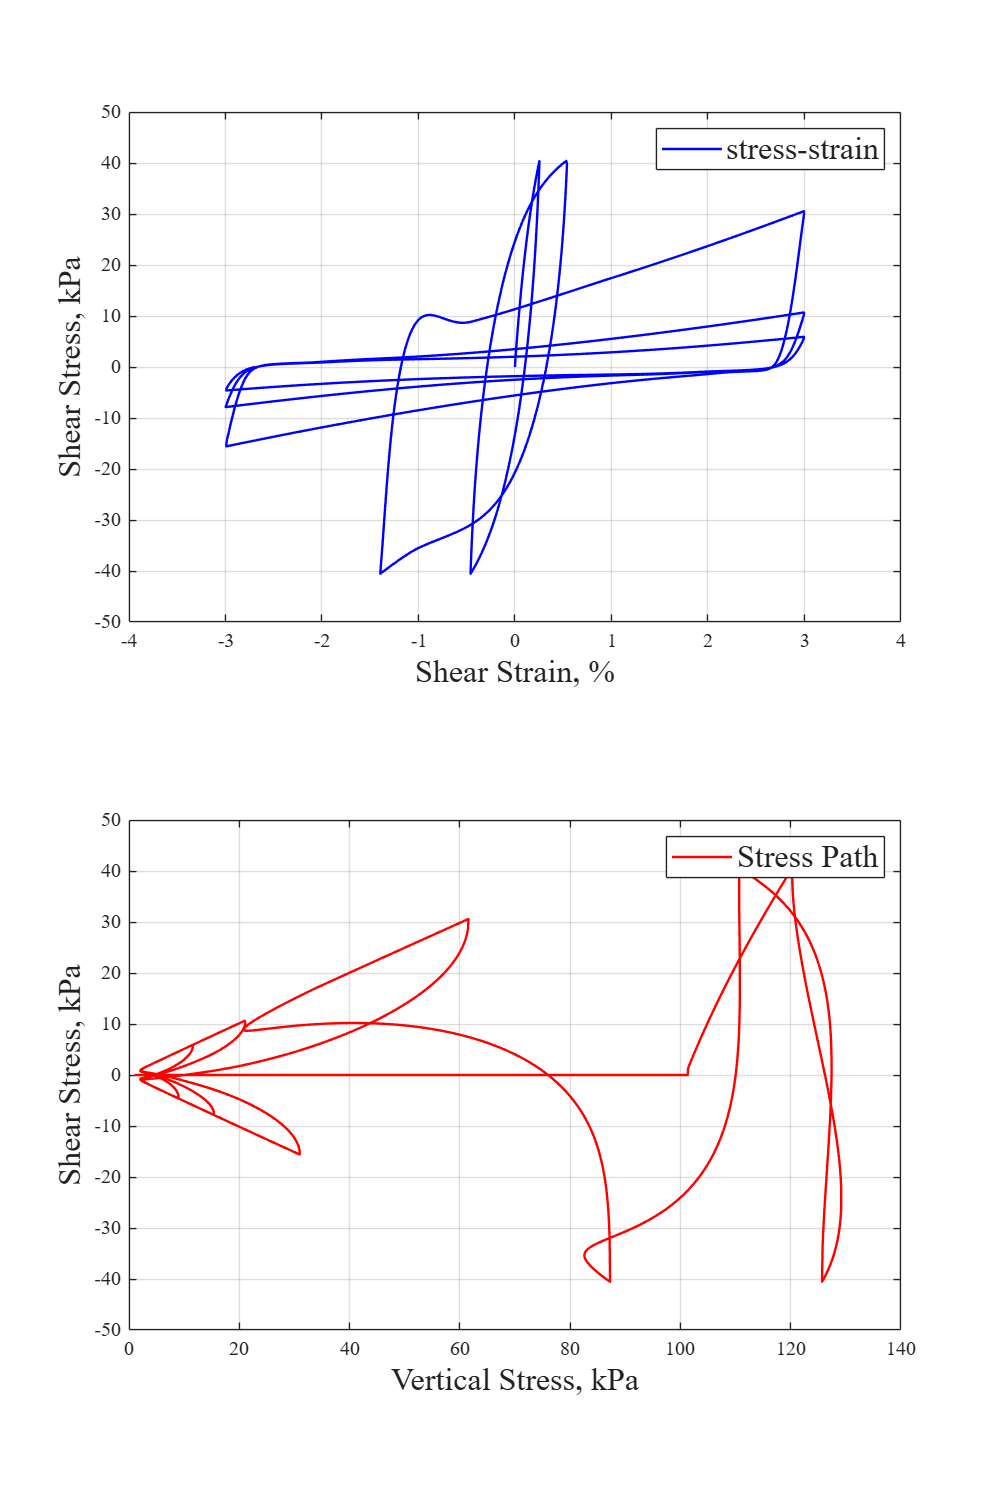


%% Post-Processing
% Read recorder output files
data_stress = readmatrix('output_data/Cycstress.txt');
data_strain = readmatrix('output_data/Cycstrain.txt');
 
% Column 1 = time, columns 2..end = stress/strain components
% Stress order: [sigmaxx, sigmayy, sigmaxy, ...]
% Strain order: [epsxx,   epsyy,   gammaxy, ...]
Stress_V    =  data_stress(:, 2) * (-1.0);  % vertical stress, compression positive
Shear_Stress =  data_stress(:, 4);           % shear stress (sigmaxy)
Shear_Strain =  data_strain(:, 4) * 100.0;  % shear strain in percent
 
figure('Units','inches','Position',[1 1 8 12]);
set(gcf, 'DefaultTextFontName', 'Times New Roman', ...
         'DefaultAxesFontName', 'Times New Roman');
 
subplot(2,1,1);
plot(Shear_Strain, Shear_Stress, 'b-', 'LineWidth', 1.2, 'DisplayName', 'stress-strain');
xlabel('Shear Strain, %',  'FontSize', 16);
ylabel('Shear Stress, kPa','FontSize', 16);
legend('FontSize', 16);
grid on;
 
subplot(2,1,2);
plot(Stress_V, Shear_Stress, 'r-', 'LineWidth', 1.2, 'DisplayName', 'Stress Path');
xlabel('Vertical Stress, kPa','FontSize', 16);
ylabel('Shear Stress, kPa',   'FontSize', 16);
legend('FontSize', 16);
grid on;